# Course 4. Example 4.1 Part2

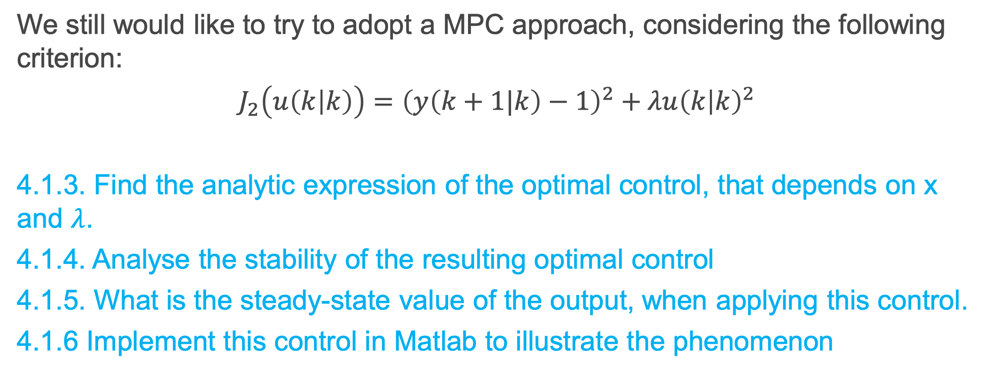

% Initialisation
clear;
close all;
clc

#### System defintion

A=[0 1;-1 0.5];
B=[0;1];
C=[1 1];
nx=size(A,1);
nu=size(B,2);
ny=size(C,1);

#### Model Prediction

Np=1;
Fy=zeros(Np*ny,nx);
Hy=zeros(Np*ny,Np*nu);

for i=1:Np
    Fy(ny*(i-1)+1:ny*i,:)=C*A^i ;
    for j=1:i
        Hy(ny*(i-1)+1:ny*i,nu*(j-1)+1:nu*j)=C*A^(i-j)*B;
    end
end


#### Objective function

lambda=1;

Q=1;
R=lambda;

Qy=zeros(ny*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qy(ny*(i-1)+1:ny*i,ny*(i-1)+1:ny*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

#### MPC Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu);
H_Np=First*(Hy'*Qy*Hy+Ru)^(-1)*Hy'*Qy; % analytic part

Analysis

EigenvaluesMPC_Np=eig(A-B*H_Np*Fy)

EigenvaluesMPC_Np =   -0.1250 + 0.6960i
  -0.1250 - 0.6960i



EigMPC_NpReal=real(EigenvaluesMPC_Np);
EigMPC_NpImag=imag(EigenvaluesMPC_Np);

#### Closed-loop implementation

Nsimu=50; % length of the simulation
xinit=[1;1];
xk=xinit;
Hquad=2*(Hy'*Qy*Hy+Ru); % can be computed offline

lambda  = 1.5

lambda = 1.5000

X = [];
Y = [];
for i=1:Nsimu
    yk = C*xk;
    X = [X xk];
    Y = [Y yk];
    uk=(1-C*A*xk)./(lambda+1); %optimal control
    xkp1=A*xk+B*uk; % the simulator is here !!
    xk=xkp1;  
end

X

X =     1.0000    1.0000   -0.3000   -0.1700    0.5970    0.4423   -0.0024    0.1349    0.3880    0.2803    0.1392    0.2179    0.2947    0.2398    0.1992    0.2362    0.2569    0.2326    0.2226    0.2382    0.2426    0.2328    0.2312    0.2372    0.2376    0.2339    0.2341    0.2362    0.2359    0.2347    0.2350    0.2357    0.2354    0.2350    0.2352    0.2355    0.2353    0.2352    0.2353    0.2354    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353
    1.0000   -0.3000   -0.1700    0.5970    0.4423   -0.0024    0.1349    0.3880    0.2803    0.1392    0.2179    0.2947    0.2398    0.1992    0.2362    0.2569    0.2326    0.2226    0.2382    0.2426    0.2328    0.2312    0.2372    0.2376    0.2339    0.2341    0.2362    0.2359    0.2347    0.2350    0.2357    0.2354    0.2350    0.2352    0.2355    0.2353    0.2352    0.2353    0.2354    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0

Y

Y =     2.0000    0.7000   -0.4700    0.4270    1.0393    0.4399    0.1324    0.5228    0.6683    0.4195    0.3571    0.5126    0.5345    0.4390    0.4354    0.4931    0.4894    0.4552    0.4608    0.4808    0.4754    0.4640    0.4683    0.4748    0.4715    0.4680    0.4703    0.4722    0.4706    0.4696    0.4707    0.4712    0.4705    0.4703    0.4707    0.4708    0.4705    0.4705    0.4706    0.4706    0.4705    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706


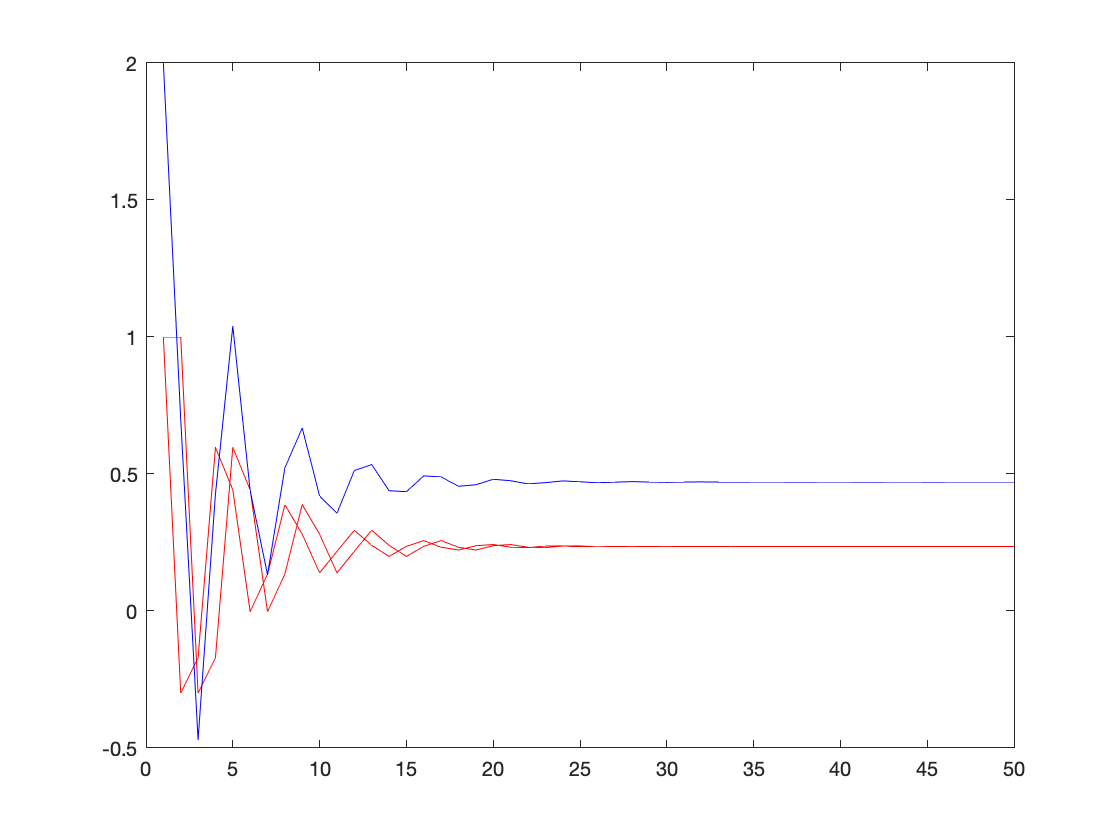

plot(1:Nsimu,X,'red');
hold on;
plot(1:Nsimu,Y,'blue');